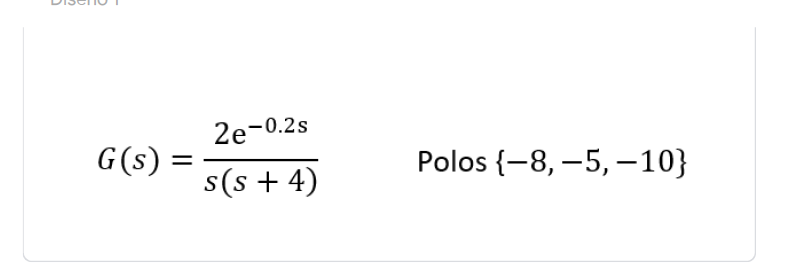

clc
clear
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


G=(20*(s+5))/(s*(s+1)*(s+4))

G =
 
     20 s + 100
  -----------------
  s^3 + 5 s^2 + 4 s
 
Continuous-time transfer function.
Model Properties


Ge=ss(G)

Ge =
 
  A = 
        x1   x2   x3
   x1   -5   -2    0
   x2    2    0    0
   x3    0  0.5    0
 
  B = 
       u1
   x1   8
   x2   0
   x3   0
 
  C = 
         x1    x2    x3
   y1     0  1.25  12.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


mp=0.095;
ts=0.74;
zeta=-log(mp)/(sqrt(pi^2+log(mp)^2))

zeta = 0.5996

wn=4/(zeta*ts) %% criterio del 2%

wn = 9.0147

sigma=zeta*wn

sigma = 5.4054

wd=wn*sqrt(1-zeta^2)

wd = 7.2143

sx=sigma+wd*i

sx = 5.4054 + 7.2143i


Ge=ss(G);
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d;
Mc=ctrb(A,B);
rank(Mc)

ans = 3


p=[5.4054 7.2143*i];
K=acker(A,B,p);

Error using acker
Vector P must have SIZE(A) elements

Alc=A-B*K;
Gc=ss(Alc,B,C,0)
F=1/dcgain(Gc)
pole(F*Gc)
step(F*Gc)
poly([-1+i -1-i -4])

Ca=(2*s+8)/(s+2);
Tc=feedback(G*Ca,1)

